# Data Averaging

 Ramsey

## Data Input 

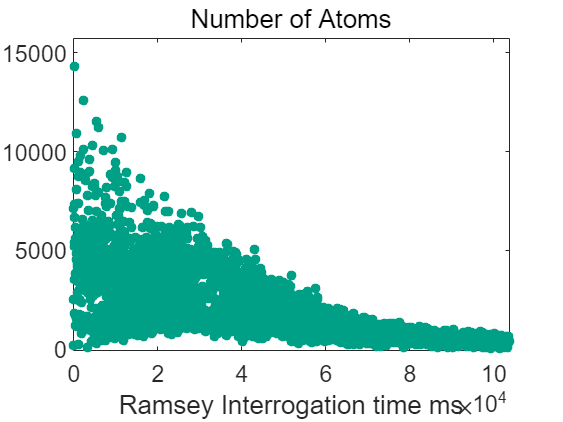

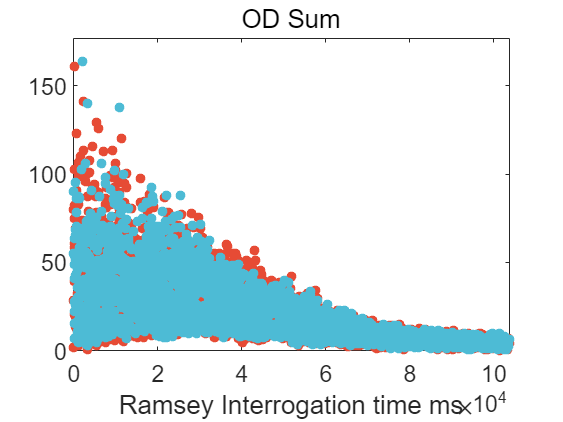

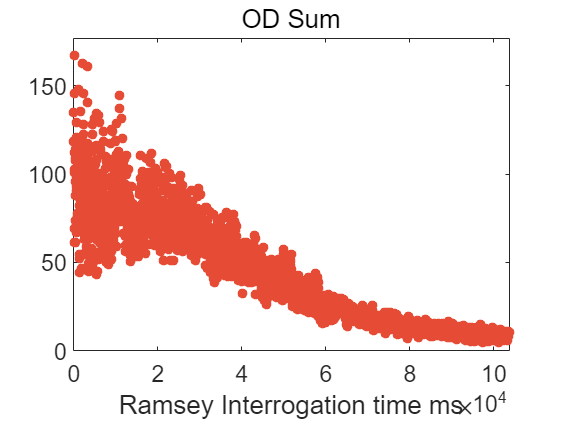

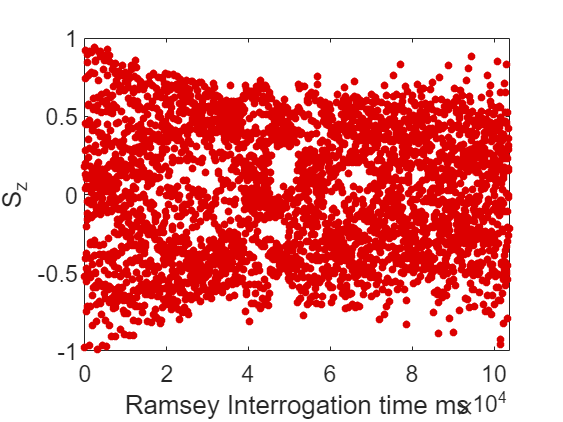

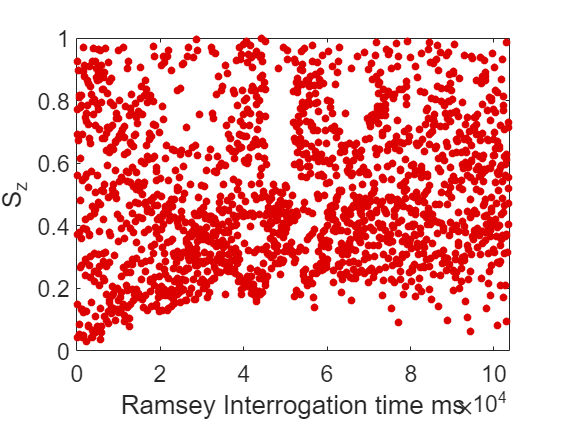

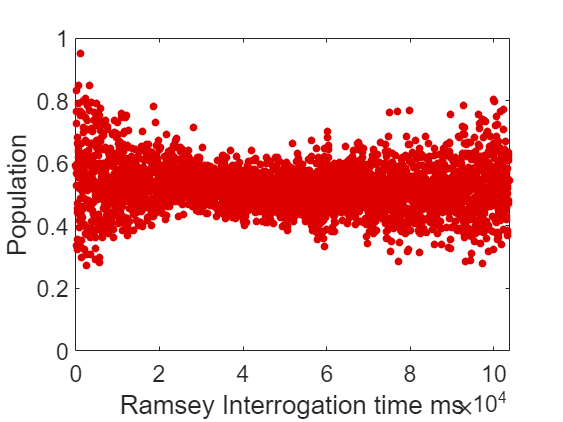

close all
clear all % Ten basic colors
main_dir='\\Artemis-pc\e\Data\2022-12-10\Abs-4329';
%main_dir='\\Artemis-pc\e\Data\2022-10-04\Abs-3612';
main_dir_0=main_dir;
load([main_dir,'\result.mat']);

clear relativeOD_fit coeff coeffoutput coefferr main_dir

colors=npg(100);


% Sz1=load(['E:\Data\2022-10-04\Abs-3612','\result.mat'],'relativeOD');
% Sz2=load(['E:\Data\2022-10-09\Abs-1026','\result.mat'],'relativeOD');

% relativeOD=[Sz1.relativeOD(1:7*341)',Sz2.relativeOD(1:end)']';


## Reshape data


x_label='Ramsey interrogation time s';
x_lim_low=0;
x_lim_high=1.050;
y_lim_low=-1.0;
y_lim_high=1.0;

precess_1_list=((0:30:1050)+6)/1000; % s
precess_1_list_plot=(-100:5:1150)/1000;

% precess_1_list=(0::500)+6; % ms
% precess_1_list_plot=0:1:600;

precess_2_list=0:20:180; % s

precess_2_list=[0,1.1:1.1:4.4,8,12,20:20:180];% s



length_0=length(relativeOD);
length_1=length(precess_1_list);
length_2=length(precess_2_list);

% reshape in row

% matrix_1=reshape(relativeOD,length_1,length_0/length_1/length_2,length_2);
% matrix_2=reshape(ODsum1+ODsum2,length_1,length_0/length_1/length_2,length_2);
% matrix_3=reshape((ODsum1+ODsum2)./ODsum3,length_1,length_0/length_1/length_2,length_2);
% 
% % clear first data run
% %matrix_1(:,1:2,:)=[];
% matrix_1(:,1,:)=[];
% 
% matrix_2(:,1,:)=[];
% 
% matrix_3(:,1,:)=[];
% 
% % clear one strange data point when 'E:\Data\2022-10-04\Abs-3612'
% % matrix_1(16,6,5)=mean(matrix_1(16,1:5,5));
% 
% %
% mean_1=mean(matrix_1,2); % mean in dim 2
% std_1=std(matrix_1,0,2); % weight 0, dim 2
% weight_1=1./std_1.^2;
% 
% mean_2=mean(mean(matrix_2,2),1);
% std_2=mean(std(matrix_2,0,2),1);
% weight_2=1./std_2.^2;
% 
% mean_3=mean(matrix_3,2),1;
% std_3=std(matrix_3,0,2),1;
% weight_3=1./std_3.^2;


matrix_1=reshape(relativeOD,length_1,length_0/length_1/length_2,length_2);
matrix_2=reshape(ODsum1+ODsum2,length_1,length_0/length_1/length_2,length_2);
matrix_3=reshape((ODsum1+ODsum2)./ODsum3,length_1,length_0/length_1/length_2,length_2);

matrix_4=reshape((ODsum1)./ODsum3,length_1,length_0/length_1/length_2,length_2);
matrix_5=reshape((ODsum2)./ODsum3,length_1,length_0/length_1/length_2,length_2);

% clear first data run
%matrix_1(:,1:2,:)=[];

matrix_1(:,1,:)=[];

matrix_2(:,1,:)=[];

matrix_3(:,1,:)=[];

matrix_4(:,1,:)=[];
matrix_5(:,1,:)=[];
% clear one strange data point when 'E:\Data\2022-10-04\Abs-3612'
% matrix_1(16,6,5)=mean(matrix_1(16,1:5,5));

%
mean_1=mean(matrix_1,2); % mean in dim 2
std_1=std(matrix_1,0,2); % weight 0, dim 2
weight_1=1./std_1.^2;

mean_2=mean(mean(matrix_2,2),1);
std_2=mean(std(matrix_2,0,2),1);
weight_2=1./std_2.^2;

mean_3=mean(matrix_3,2);
std_3=std(matrix_3,0,2);
weight_3=1./std_3.^2;


mean_4=mean(matrix_4,2);
std_4=std(matrix_4,0,2);
weight_4=1./std_4.^2;

mean_5=mean(matrix_5,2);
std_5=std(matrix_5,0,2);
weight_5=1./std_5.^2;


%  use data in form of (:,:,i)


## Sinusoidal fitting

fi =      常规模型:
     fi(x) = a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d
     系数(置信边界为 95%):
       a1 =       0.755  (0.6478, 0.8622)
       a3 =      0.1445  (0.03356, 0.2554)
       a5 =       0.076  (-0.03022, 0.1822)
       b1 =       2.527  (2.464, 2.59)
       c1 =      -2.797  (-3.049, -2.546)
       c3 =      -2.317  (-3.278, -1.356)
       c5 =      -11.16  (-13.06, -9.255)
       d =    -0.02571  (-0.1115, 0.06007)

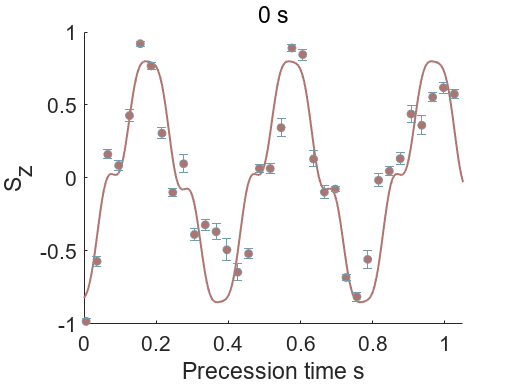

fi =      常规模型:
     fi(x) = a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d
     系数(置信边界为 95%):
       a1 =      0.6292  (0.5647, 0.6936)
       a3 =      0.1876  (0.1202, 0.2549)
       a5 =     0.06863  (0.0004383, 0.1368)
       b1 =       2.542  (2.493, 2.592)
       c1 =       2.489  (2.299, 2.679)
       c3 =    0.008085  (-0.5522, 0.5684)
       c5 =       3.737  (2.408, 5.066)
       d =     0.00529  (-0.04121, 0.05179)

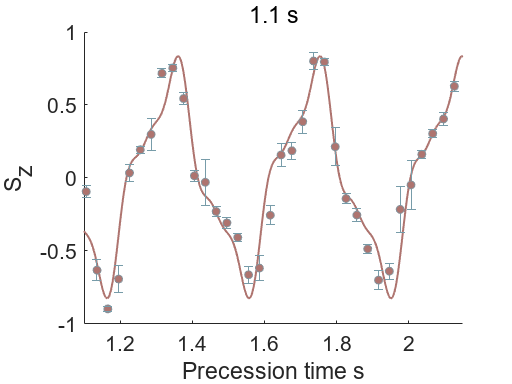

fi =      常规模型:
     fi(x) = a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d
     系数(置信边界为 95%):
       a1 =      0.6093  (0.5722, 0.6464)
       a3 =      0.1559  (0.116, 0.1958)
       a5 =     0.02225  (-0.01719, 0.0617)
       b1 =       2.565  (2.528, 2.603)
       c1 =       1.442  (1.299, 1.584)
       c3 =       2.999  (2.568, 3.429)
       c5 =       4.499  (2.84, 6.157)
       d =        0.02  (-0.004708, 0.04471)

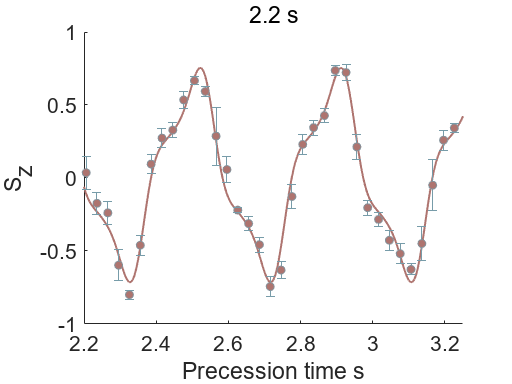

fi =      常规模型:
     fi(x) = a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d
     系数(置信边界为 95%):
       a1 =      0.6643  (0.64, 0.6885)
       a3 =      0.1305  (0.104, 0.157)
       a5 =     0.01335  (-0.01108, 0.03778)
       b1 =       2.586  (2.563, 2.61)
       c1 =      0.3517  (0.2654, 0.4381)
       c3 =     -0.8099  (-1.103, -0.5169)
       c5 =      -1.503  (-3.525, 0.5184)
       d =     0.01172  (-0.005263, 0.02871)

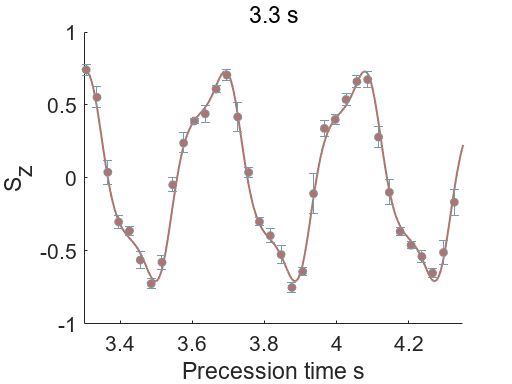

fi =      常规模型:
     fi(x) = a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d
     系数(置信边界为 95%):
       a1 =      0.6237  (0.6092, 0.6382)
       a3 =      0.1362  (0.1186, 0.1538)
       a5 =     0.01714  (0.0008957, 0.03337)
       b1 =       2.561  (2.549, 2.573)
       c1 =     -0.4869  (-0.5372, -0.4366)
       c3 =       2.583  (2.417, 2.749)
       c5 =      0.5268  (-0.4445, 1.498)
       d =     0.01072  (0.0005719, 0.02087)

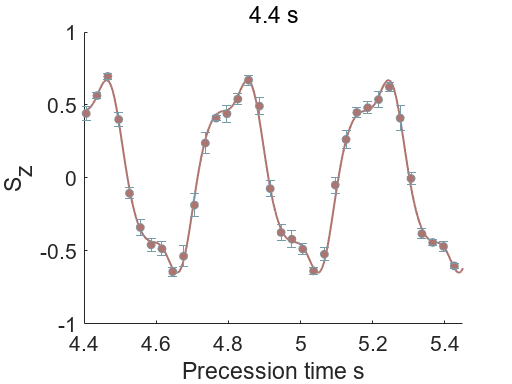

fi =      常规模型:
     fi(x) = a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d
     系数(置信边界为 95%):
       a1 =      0.5668  (0.5574, 0.5762)
       a3 =      0.1458  (0.1338, 0.1578)
       a5 =     0.01826  (0.00689, 0.02962)
       b1 =       2.577  (2.568, 2.587)
       c1 =       1.512  (1.478, 1.545)
       c3 =      0.5918  (0.4847, 0.6989)
       c5 =      0.6614  (0.1192, 1.204)
       d =     0.01484  (0.007924, 0.02175)

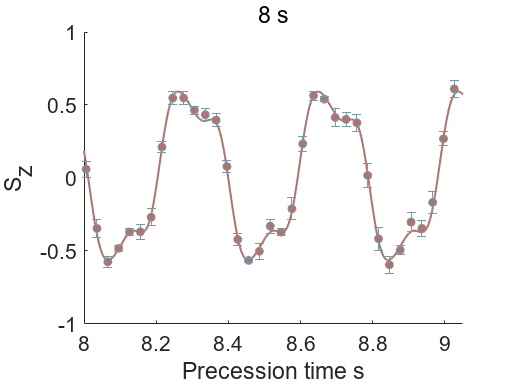

fi =      常规模型:
     fi(x) = a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d
     系数(置信边界为 95%):
       a1 =      0.5593  (0.5413, 0.5773)
       a3 =      0.1563  (0.1367, 0.1759)
       a5 =     0.01813  (-0.002211, 0.03847)
       b1 =       2.587  (2.573, 2.601)
       c1 =      -2.547  (-2.611, -2.482)
       c3 =     -0.8673  (-1.066, -0.6686)
       c5 =      -9.308  (-10.45, -8.17)
       d =     0.01919  (0.00519, 0.0332)

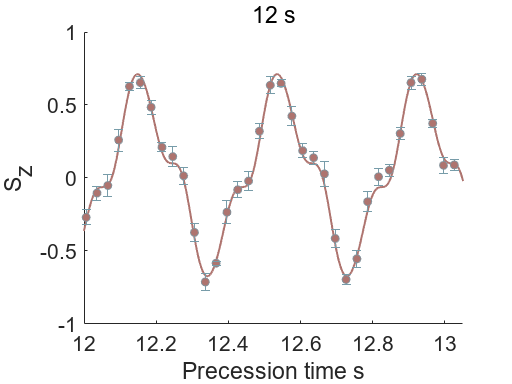

fi =      常规模型:
     fi(x) = a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d
     系数(置信边界为 95%):
       a1 =      0.5352  (0.5227, 0.5478)
       a3 =      0.1679  (0.156, 0.1797)
       a5 =    0.002973  (-0.009771, 0.01572)
       b1 =       2.582  (2.572, 2.592)
       c1 =       2.056  (2.01, 2.102)
       c3 =       2.994  (2.852, 3.135)
       c5 =       4.098  (-0.5228, 8.719)
       d =     0.02084  (0.01142, 0.03025)

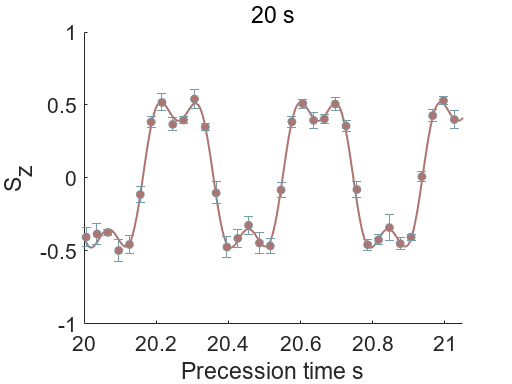

fi =      常规模型:
     fi(x) = a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d
     系数(置信边界为 95%):
       a1 =      0.5251  (0.496, 0.5541)
       a3 =      0.1558  (0.1294, 0.1823)
       a5 =    0.007322  (-0.01658, 0.03123)
       b1 =       2.579  (2.557, 2.6)
       c1 =      0.8816  (0.786, 0.9772)
       c3 =       3.119  (2.835, 3.403)
       c5 =      -2.825  (-6.934, 1.285)
       d =     0.02796  (0.007149, 0.04878)

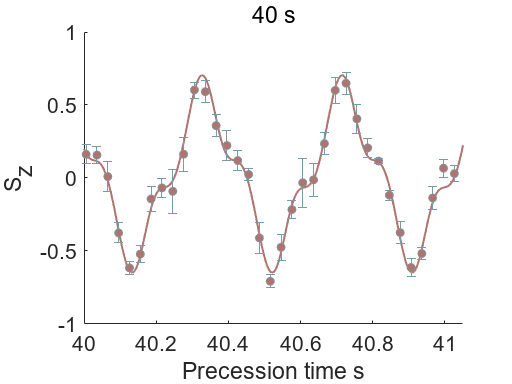

fi =      常规模型:
     fi(x) = a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d
     系数(置信边界为 95%):
       a1 =      0.5093  (0.4917, 0.5268)
       a3 =       0.144  (0.1259, 0.1621)
       a5 =     0.02244  (0.005634, 0.03925)
       b1 =       2.582  (2.567, 2.597)
       c1 =     -0.3409  (-0.3936, -0.2881)
       c3 =      -9.378  (-9.559, -9.197)
       c5 =      -1.416  (-2.197, -0.6349)
       d =   -0.002648  (-0.01562, 0.01032)

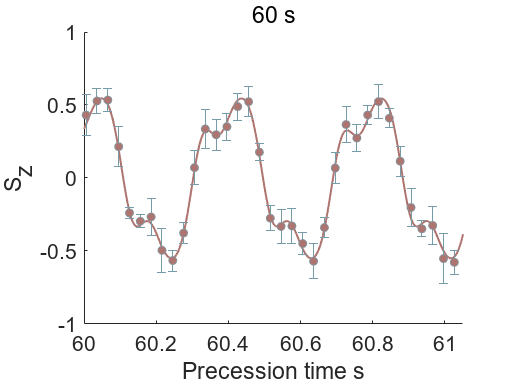

fi =      常规模型:
     fi(x) = a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d
     系数(置信边界为 95%):
       a1 =      0.5252  (0.5095, 0.541)
       a3 =      0.1326  (0.1188, 0.1463)
       a5 =     0.01186  (-0.00259, 0.0263)
       b1 =       2.598  (2.585, 2.611)
       c1 =      -1.714  (-1.759, -1.669)
       c3 =      -9.422  (-9.586, -9.258)
       c5 =      -2.609  (-3.903, -1.314)
       d =     0.01105  (-0.0008894, 0.02299)

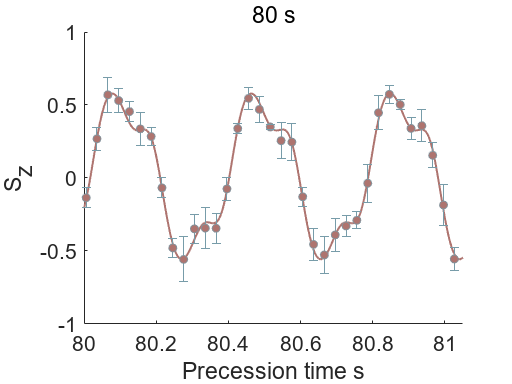

fi =      常规模型:
     fi(x) = a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d
     系数(置信边界为 95%):
       a1 =      0.4313  (0.4035, 0.4592)
       a3 =      0.1437  (0.1154, 0.1721)
       a5 =    0.007998  (-0.017, 0.033)
       b1 =       2.586  (2.567, 2.604)
       c1 =      -2.626  (-2.722, -2.53)
       c3 =       3.526  (3.23, 3.822)
       c5 =       7.642  (4.037, 11.25)
       d =     0.02464  (0.004676, 0.0446)

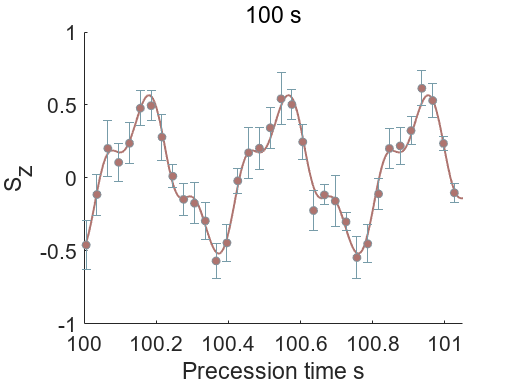

fi =      常规模型:
     fi(x) = a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d
     系数(置信边界为 95%):
       a1 =      0.4592  (0.4317, 0.4868)
       a3 =      0.1357  (0.109, 0.1625)
       a5 =     0.03152  (0.003345, 0.0597)
       b1 =       2.613  (2.585, 2.642)
       c1 =       2.474  (2.355, 2.594)
       c3 =      -2.751  (-3.123, -2.378)
       c5 =      -7.928  (-8.936, -6.919)
       d =     0.01494  (-0.004652, 0.03452)

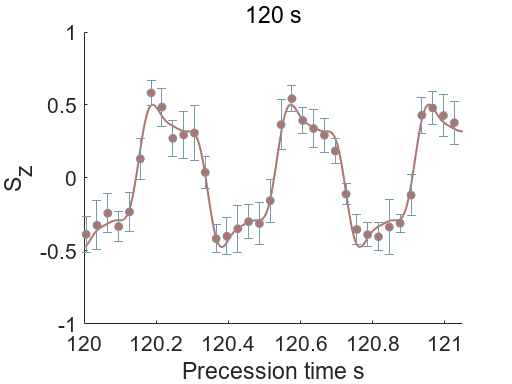

fi =      常规模型:
     fi(x) = a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d
     系数(置信边界为 95%):
       a1 =      0.4679  (0.4521, 0.4836)
       a3 =      0.1224  (0.1047, 0.14)
       a5 =    0.008519  (-0.01116, 0.02819)
       b1 =       2.598  (2.581, 2.615)
       c1 =        1.01  (0.9287, 1.092)
       c3 =      -2.351  (-2.621, -2.081)
       c5 =      -3.217  (-5.441, -0.9929)
       d =    0.001068  (-0.01249, 0.01463)

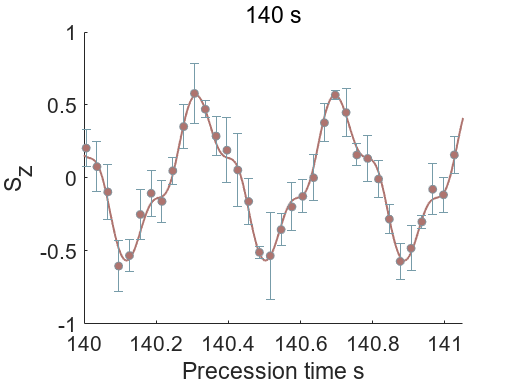

fi =      常规模型:
     fi(x) = a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d
     系数(置信边界为 95%):
       a1 =      0.4406  (0.4074, 0.4739)
       a3 =      0.1245  (0.09243, 0.1566)
       a5 =     0.03657  (0.003607, 0.06953)
       b1 =       2.598  (2.571, 2.624)
       c1 =    -0.07315  (-0.1807, 0.03439)
       c3 =       -1.98  (-2.322, -1.638)
       c5 =       1.722  (0.7638, 2.681)
       d =     0.01449  (-0.007395, 0.03638)

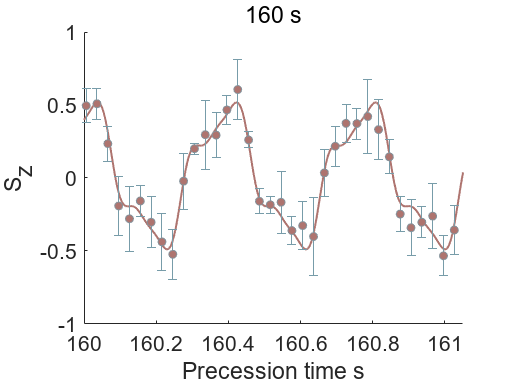

fi =      常规模型:
     fi(x) = a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d
     系数(置信边界为 95%):
       a1 =      0.4858  (0.4443, 0.5272)
       a3 =       0.105  (0.05964, 0.1504)
       a5 =     0.02215  (-0.02401, 0.06831)
       b1 =       2.552  (2.512, 2.591)
       c1 =      -1.258  (-1.419, -1.097)
       c3 =      -1.318  (-1.859, -0.7772)
       c5 =      -15.24  (-17.23, -13.24)
       d =    -0.02852  (-0.06122, 0.004176)

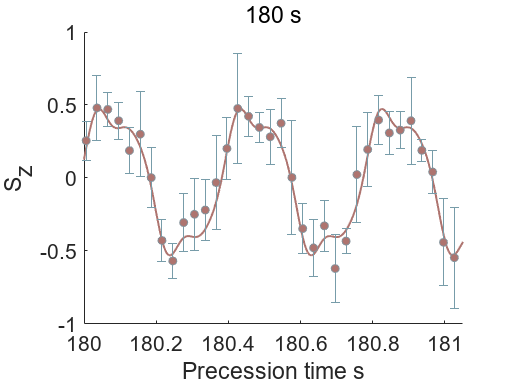

eqn='a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d';
startpoints=[0.6 0.2 0.01 2.58 0 0 0 0];
lower=[0 0 0 2 -3.142*2 -3.142*4 -3.142*6 -1];
upper=[1 1 1 3  3.142*2  3.142*4  3.142*6  1];

chilist=[];

amp_1=zeros(1,length_2);
amp_3=zeros(1,length_2);
amp_5=zeros(1,length_2);

amp_err_1=zeros(1,length_2);
amp_err_3=zeros(1,length_2);
amp_err_5=zeros(1,length_2);

c_1=zeros(1,length_2);
c_3=zeros(1,length_2);
c_5=zeros(1,length_2);

c_err_1=zeros(1,length_2);
c_err_3=zeros(1,length_2);
c_err_5=zeros(1,length_2);


freq_1=zeros(1,length_2);
freq_err_1=zeros(1,length_2);

chilist=[];
chilist_reduced=[];

%h=figure;

for i = 1:size(mean_1,3)
    %for i=1:1
    fi=fit(precess_1_list',mean_1(:,:,i),eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',weight_1(:,:,i));
    fi_result{i}=fi;
    fi
    h=figure;
    hold on
    plot(precess_1_list_plot+precess_2_list(i),fi(precess_1_list_plot),'LineWidth',1.5,'Color',colors(5,:));
    hold on
    % plot(precess_1_list,mean_1(:,:,i)','.','MarkerSize',15,'Color',colors(8,:));

    I_se=errorbar(precess_1_list+precess_2_list(i),mean_1(:,:,i),std_1(:,:,i),'o');

    title([num2str(precess_2_list(i)),' s']);
    ylim([-1 1]);
    ylabel('S_z');
    xlabel('Precession time s');
    set(gca,'FontSize',16);
    xlim([x_lim_low+precess_2_list(i) x_lim_high+precess_2_list(i)])
    ylim([y_lim_low y_lim_high])

    I_se.Color=colors(9,:);
    I_se.MarkerSize=6;
    I_se.MarkerEdgeColor=colors(8,:);
    I_se.MarkerFaceColor=colors(5,:);

    amp_1(i)=fi.a1;
    amp_3(i)=fi.a3;
    amp_5(i)=fi.a5;

    c_1(i)=fi.c1;
    c_3(i)=fi.c3;
    c_5(i)=fi.c5;

    freq_1=fi.b1;

    temp = confint(fi);
    amp_err_1(i) = (temp(2)-temp(1))./4;
    amp_err_3(i) = (temp(4)-temp(3))./4;
    amp_err_5(i) = (temp(6)-temp(5))./4;

    c_err_1(i) = (temp(10)-temp(9))./4;
    c_err_3(i) = (temp(12)-temp(11))./4;
    c_err_5(i) = (temp(14)-temp(13))./4;

    freq_err_1=(temp(8)-temp(7))./4;

    chilist(i)=sum(((mean_1(:,:,i)-fi(precess_1_list))./std_1(:,:,i)).^2);
    chilist_reduced(i)=chilist(i)/(length(precess_1_list)-8);
    %     coefferr(i,:).*sqrt(chilist(i))
    saveas(h,[main_dir_0,'\Figure_',num2str(i),'.png'])
    savefig(h,[main_dir_0,'\Figure_',num2str(i),'.fig'])
end

## Sindusal fitting two state

ans = -0.0624

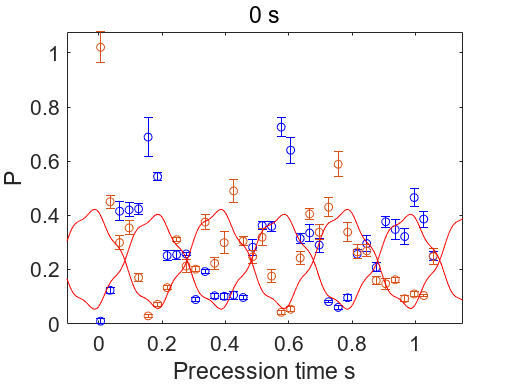

ans = -0.0859

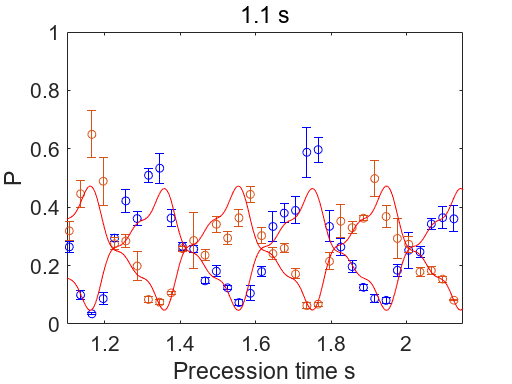

ans = 0.0245

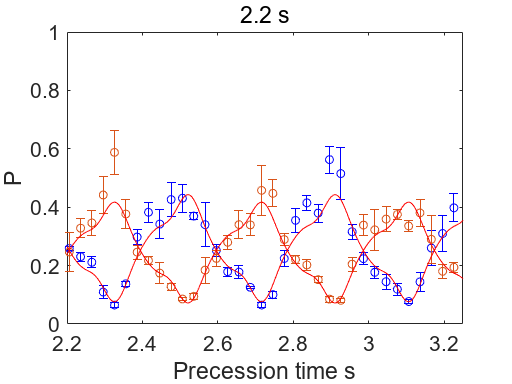

ans = 0.0194

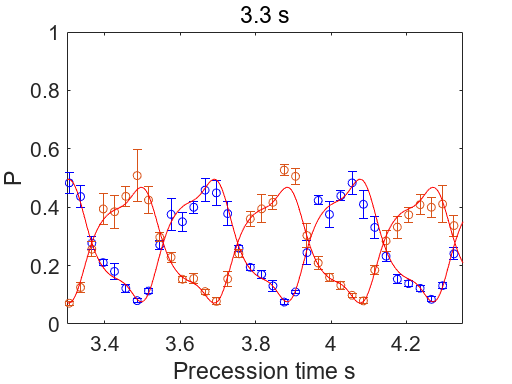

ans = 0.0117

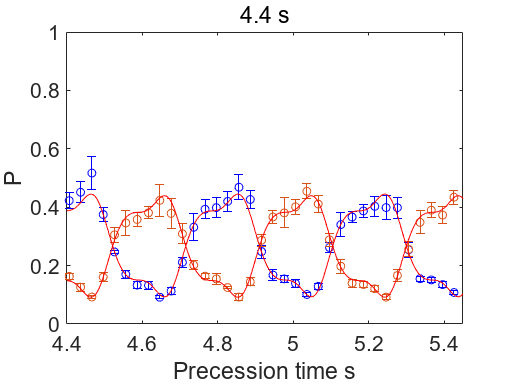

ans = 0.0086

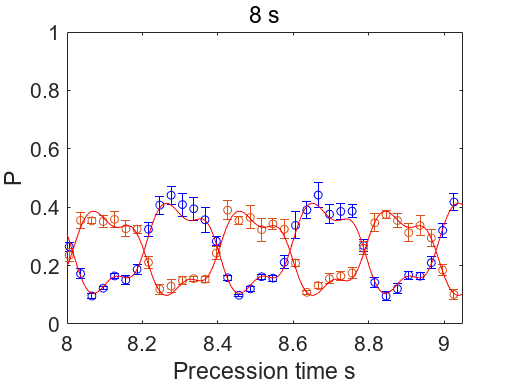

ans = 0.0318

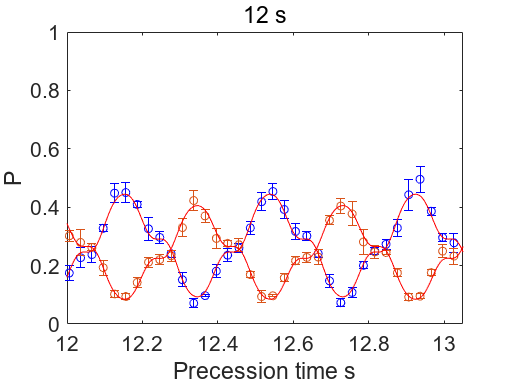

ans = -0.0047

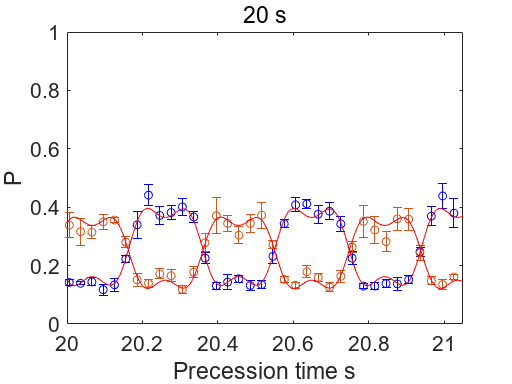

ans = -0.0051

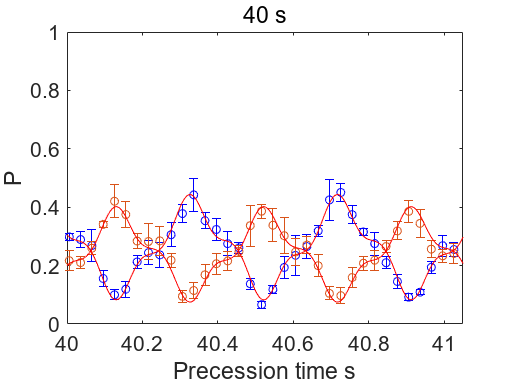

ans = 0.0089

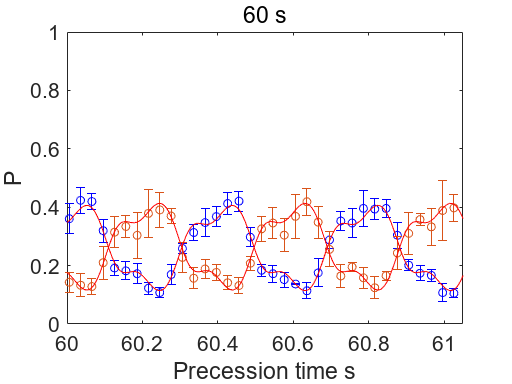

ans = -0.0091

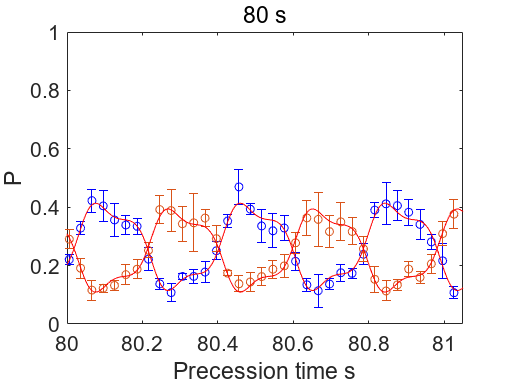

ans = -0.0036

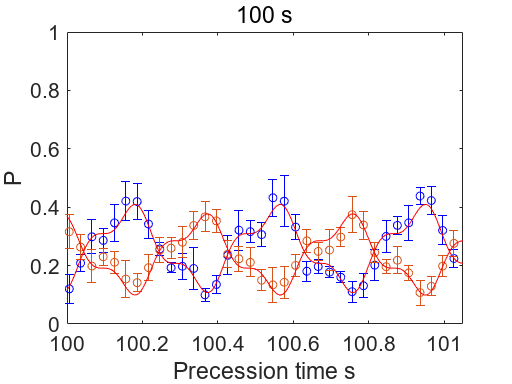

ans = 0.0351

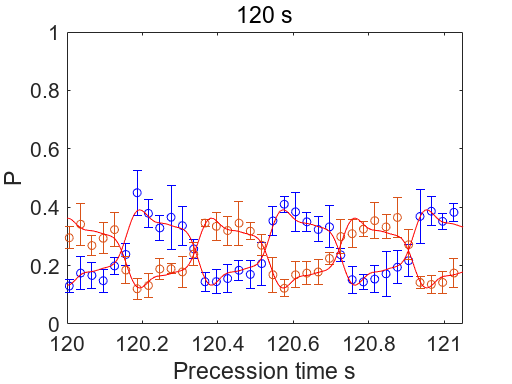

ans = -0.0221

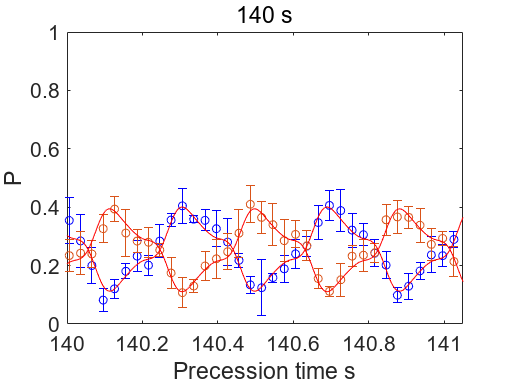

ans = 0.0222

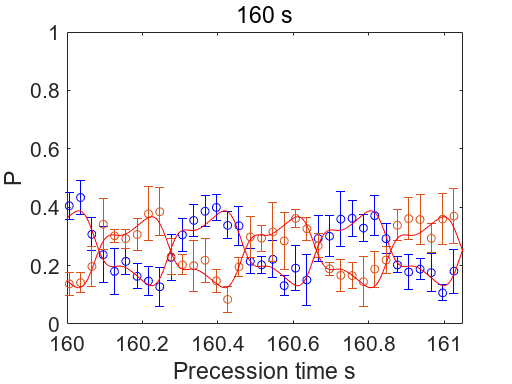

ans = -0.0318

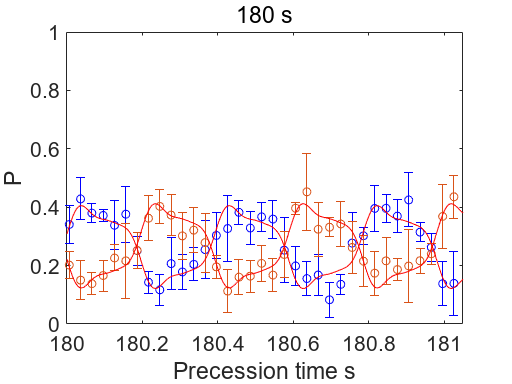

eqn='a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d';
startpoints=[0.6 0.2 0.01 2.58 0 0 0 0];
lower=[0 0 0 2 -3.142*2 -3.142*4 -3.142*6 -1];
upper=[1 1 1 3  3.142*2  3.142*4  3.142*6  1];

chilist=[];
chilist_reduced=[];

[p_1,p_2,contrast,freq,phase_1]=deal(zeros(1,size(mean_1,3)));
[p_1_err,p_2_err,contrast_err,freq_err,phase_1_err]=deal(zeros(1,size(mean_1,3)));


for i = 1:size(mean_1,3)
    %for i=1:1
    x_cell={precess_1_list,precess_1_list};
    y_cell={transpose(mean_4(:,:,i)),transpose(mean_5(:,:,i))};
    w_cell={transpose(weight_4(:,:,i)),transpose(weight_5(:,:,i))};
    mdl1 = @(beta,x) beta(1)/2*(1+beta(3)*cos(2*pi*beta(6)*x+beta(7))+beta(4)*cos(2*pi*3*beta(6)*x+beta(8))+beta(5)*cos(2*pi*5*beta(6)*x+beta(9)));
    mdl2 = @(beta,x) beta(2)/2*(1-beta(3)*cos(2*pi*beta(6)*x+beta(7))-beta(4)*cos(2*pi*3*beta(6)*x+beta(8))-beta(5)*cos(2*pi*5*beta(6)*x+beta(9)));
    mdl_cell = {mdl1, mdl2};
    beta0=[1 1 1 1 1 2.58 0 0 0];
    [beta,r,J,Sigma,mse,errorparam,robustw] = nlinmultifit(x_cell, y_cell, mdl_cell, beta0,'weights',w_cell);
    % Calculate model predictions and confidence intervals
    [ypred1,delta1] = nlpredci(mdl1,precess_1_list_plot,beta,r,'covar',Sigma);
    [ypred2,delta2] = nlpredci(mdl2,precess_1_list_plot,beta,r,'covar',Sigma);
    beta(5)
    % Calculate parameter confidence intervals
    ci = nlparci(beta,r,'Jacobian',J);

    figure_2_part=figure;
    hold all;
    box on;
    %scatter(precess_1_list+precess_2_list(i),transpose(mean_4(:,:,i)));
    %scatter(precess_1_list+precess_2_list(i),transpose(mean_5(:,:,i)));
    errorbar(precess_1_list+precess_2_list(i),mean_4(:,:,i),std_4(:,:,i),'o','Color','blue');
    errorbar(precess_1_list+precess_2_list(i),mean_5(:,:,i),std_5(:,:,i),'o');
    plot(precess_1_list_plot+precess_2_list(i),ypred1,'Color','red');
    plot(precess_1_list_plot+precess_2_list(i),ypred2,'Color','red');

    title([num2str(precess_2_list(i)),' s']);
    ylim([0 1]);
    ylabel('P');
    xlabel('Precession time s');
    set(gca,'FontSize',16);
    xlim([x_lim_low+precess_2_list(i) x_lim_high+precess_2_list(i)])
    ylim([0 y_lim_high])


    p_1(i)=beta(1);
    p_2(i)=beta(2);
    contrast(i)=abs(beta(3))+abs(beta(4))+abs(beta(5));
    freq(i)=beta(6);
    %phase_1(i)=beta(5);

    beta_err=(ci(10:18)-ci(1:9))./4;
    p_1_err(i)=beta_err(1);
    p_2_err(i)=beta_err(2);
    contrast_err(i)=sqrt(beta_err(3).^2+beta_err(4).^2+beta_err(5).^2);
    freq_err(i)=beta_err(6);
    %phase_1_err(i)=beta_err(1);
        saveas(figure_2_part,[main_dir_0,'\Figure_p2_',num2str(i),'.png'])
    savefig(figure_2_part,[main_dir_0,'\Figure_p2_',num2str(i),'.fig'])

end

## Plot contrast decay - two

f_contrast_decay=figure;
eqn='a*exp(-x/b)+c*exp(-x/d)';
startpoints=[1 1 1 1000];
lower=[0 0.1 0.5 500];
upper=[1 100 1 10000];
fi=fit(precess_2_list',contrast',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./contrast_err.^2);
fi

fi =      常规模型:
     fi(x) = a*exp(-x/b)+c*exp(-x/d)
     系数(置信边界为 95%):
       a =      0.1301  (0.03766, 0.2225)
       b =       6.156  (-2.358, 14.67)
       c =      0.7124  (0.6666, 0.7582)
       d =       961.2  (324, 1598)

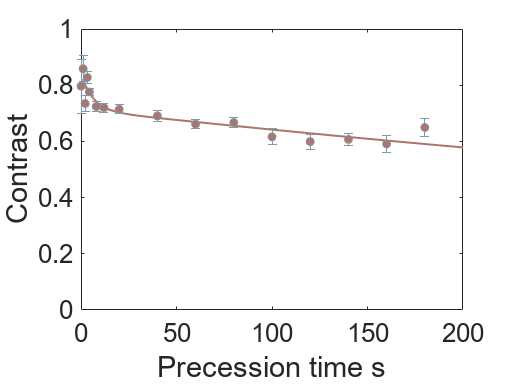

plot((1:1:200),fi(1:1:200),'LineWidth',1.5,'Color',colors(5,:));
hold on
hold all
h1=errorbar(precess_2_list',contrast,contrast_err,'o');
hold on;
%h1=errorbar(precess_2_list',coeffoutput(:,1),coefferr(:,1),'o');
ylabel('Contrast');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([0 1])
h1.Color=colors(9,:);
h1.MarkerSize=6;
h1.MarkerEdgeColor=colors(8,:);
h1.MarkerFaceColor=colors(5,:);
set(gca,'YScale','linear')
ylim([0 1])

savefig(f_contrast_decay,[main_dir_0,'\ContrastDecay.fig'])
saveas(f_contrast_decay,[main_dir_0,'\ContrastDecay.png'])

## Plot population decay - two

f_population_decay=figure;
hold all
h1=errorbar(precess_2_list',p_1,p_1_err,'o');
h2=errorbar(precess_2_list',p_2,p_2_err,'o');

% eqn='(1-c)*exp(-(x/b)^1)+c+0*a';
% startpoints=[10000 100 0.5 ];
% lower=[0 0 0.5];
% upper=[1000000 10000 0.6];

eqn='a*exp(-x^1/b^1)+c';
startpoints=[0.5 1 1];
lower=[0 0 0];
upper=[1 200 1];


fi_pop_coherent=fit(precess_2_list',p_1',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./p_1_err.^2);
fi_pop_coherent_p1=fi_pop_coherent

fi_pop_coherent_p1 =      常规模型:
     fi_pop_coherent_p1(x) = a*exp(-x^1/b^1)+c
     系数(置信边界为 95%):
       a =   2.372e-11  (固定在边界处)
       b =    0.003587  (-Inf, Inf)
       c =      0.5266  (0.5196, 0.5335)

plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',2,'Color',colors(5,:));

fi_pop_coherent=fit(precess_2_list',p_2',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./p_2_err.^2);
fi_pop_coherent_p2=fi_pop_coherent

fi_pop_coherent_p2 =      常规模型:
     fi_pop_coherent_p2(x) = a*exp(-x^1/b^1)+c
     系数(置信边界为 95%):
       a =     0.04804  (-0.06362, 0.1597)
       b =         4.2  (-7.456, 15.86)
       c =      0.4954  (0.4811, 0.5098)

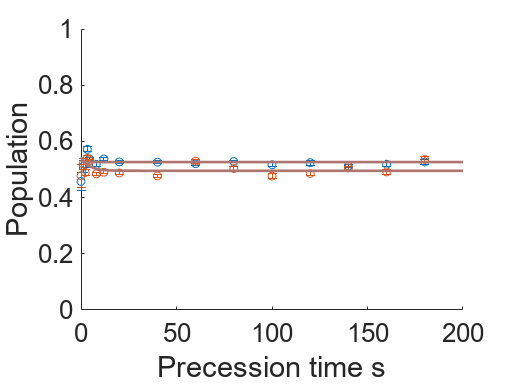

plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',2,'Color',colors(5,:));

ylabel('Population');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([0 1])
set(gca,'YScale','linear')



figure
hold all
h1=errorbar(precess_2_list',p_1,p_1_err,'o');
h2=errorbar(precess_2_list',p_2,p_2_err,'o');
plot((0:1:200),fi_pop_coherent_p1(0:1:200),'LineWidth',2,'Color',colors(5,:));
plot((0:1:200),fi_pop_coherent_p2(0:1:200),'LineWidth',2,'Color',colors(5,:));
ylabel('Population');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([0 1])
set(gca,'YScale','linear')


figure
hold all
fi_pop_coherent=fit(precess_2_list',(p_1+p_2)'./2,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./p_1_err.^2+1./p_2_err.^2);
fi_pop_coherent_p1_p2=fi_pop_coherent

fi_pop_coherent_p1_p2 =      常规模型:
     fi_pop_coherent_p1_p2(x) = a*exp(-x^1/b^1)+c
     系数(置信边界为 95%):
       a =       0.028  (-0.02898, 0.08498)
       b =       5.852  (-10.99, 22.69)
       c =      0.5105  (0.5009, 0.5201)

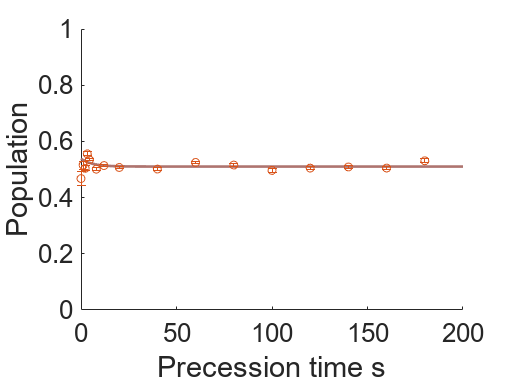

plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',2,'Color',colors(5,:));

h1=errorbar(precess_2_list',(p_1+p_2)./2,sqrt(p_1_err.^2+p_2_err.^2)/2,'o');
ylabel('Population');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([0 1])
set(gca,'YScale','linear')

## population decay

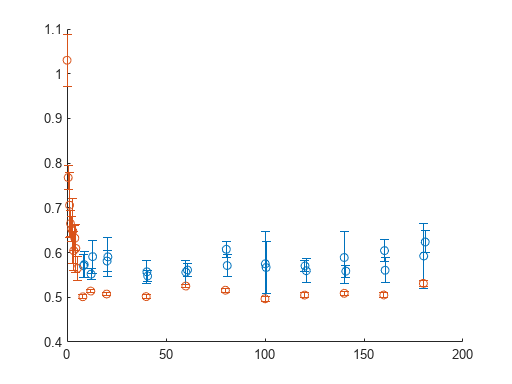

p_average=(p_1+p_2)./2;
p_average_err=sqrt(p_1_err.^2+p_2_err.^2)/2;

mean_3_1=reshape(mean_3,18,1,[]);
std_3_1=reshape(std_3,18,1,[]);

[mean_3_1_max,mean_3_1_max_id]=max(mean_3_1);
mean_3_1_max_std=std_3_1(mean_3_1_max_id);
population_timelist=precess_1_list(squeeze(mean_3_1_max_id))+sort([precess_2_list,precess_2_list+0.54]);
mean_3_max=squeeze(mean_3_1_max);
mean_3_max_std=squeeze(mean_3_1_max_std);
mean_3_max_weight=1./mean_3_max_std.^2;

figure
hold all
errorbar(population_timelist,mean_3_max,mean_3_max_std,'o')

mean_3_max=transpose(mean_3_max);
mean_3_max_std=transpose(mean_3_max_std);

mean_3_max(population_timelist>7)=[];
mean_3_max_std(population_timelist>7)=[];
population_timelist(population_timelist>7)=[];

population_timelist_2=precess_2_list;
p_average(population_timelist_2<7)=[];
p_average_err(population_timelist_2<7)=[];
population_timelist_2(population_timelist_2<7)=[];

population_timelist_all=[population_timelist,population_timelist_2];
p_average_all=[mean_3_max,p_average];
p_average_err_all=[mean_3_max_std,p_average_err];

errorbar(population_timelist_all,p_average_all,p_average_err_all,'o')



loss_factor=1/1.03;
p_average_all=p_average_all*loss_factor;
p_average_err_all=p_average_err_all*loss_factor;

eqn='a*exp(-x^1/b^1)+(1-a)';
startpoints=[0.5 1];
lower=[0 0 ];
upper=[1 20];

fi_pop_coherent=fit(population_timelist_all',p_average_all',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./p_average_err_all.^2);

fi_pop_coherent

fi_pop_coherent =      常规模型:
     fi_pop_coherent(x) = a*exp(-x^1/b^1)+(1-a)
     系数(置信边界为 95%):
       a =      0.5044  (0.4988, 0.51)
       b =       1.482  (0.98, 1.983)

f_pop_decay=figure

f_pop_decay =   Figure (113) - 属性:

      Number: 113
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


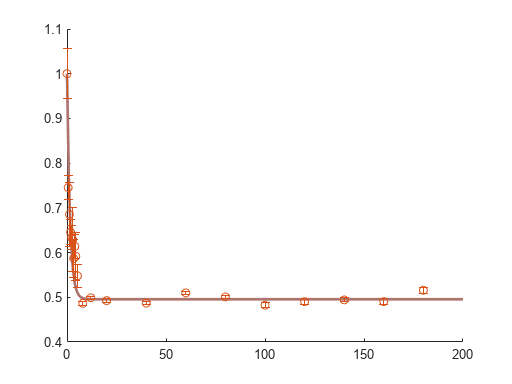

hold all
plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',2,'Color',colors(5,:));
errorbar(population_timelist_all,p_average_all,p_average_err_all,'o')


savefig(f_pop_decay,[main_dir_0,'\PopulationDecay.fig'])
saveas(f_pop_decay,[main_dir_0,'\Population decay.png'])

##  Plot population decay - two part

% for i = 1:size(mean_1,3)
%     figure;
%     hold all;
%     box on;
%     errorbar(precess_1_list+precess_2_list(i),mean_4(:,:,i)+mean_5(:,:,i),sqrt(std_4(:,:,i).^2+std_5(:,:,i).^2),'o','Color','blue');
% 
%     title([num2str(precess_2_list(i)),' s']);
%     ylim([0 1]);
%     ylabel('P');
%     xlabel('Precession time s');
%     set(gca,'FontSize',16);
%     xlim([x_lim_low+precess_2_list(i) x_lim_high+precess_2_list(i)])
%     ylim([0 y_lim_high])
% end

## Plot contrast decay

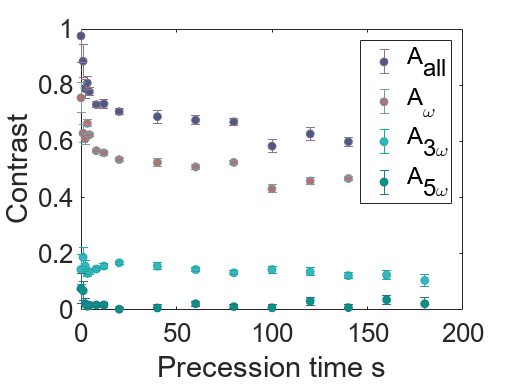


% amplitude
f_amp=figure;
hold on;

amp_all=amp_1+amp_3+amp_5;
amp_all_err=sqrt(amp_err_1.^2+amp_err_3.^2+amp_err_5.^2);
f_amp_h_all=errorbar(precess_2_list',amp_all,amp_all_err,'o');
f_amp_h1=errorbar(precess_2_list',amp_1,amp_err_1,'o');
f_amp_h3=errorbar(precess_2_list',amp_3,amp_err_5,'o');
f_amp_h5=errorbar(precess_2_list',amp_5,amp_err_5,'o');


ylabel('Contrast');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([0 1])

f_amp_h1.Color=colors(9,:);
f_amp_h1.MarkerSize=6;
f_amp_h1.MarkerEdgeColor=colors(8,:);
f_amp_h1.MarkerFaceColor=colors(5,:);

f_amp_h3.Color=colors(19,:);
f_amp_h3.MarkerSize=6;
f_amp_h3.MarkerEdgeColor=colors(18,:);
f_amp_h3.MarkerFaceColor=colors(15,:);

f_amp_h5.Color=colors(29,:);
f_amp_h5.MarkerSize=6;
f_amp_h5.MarkerEdgeColor=colors(28,:);
f_amp_h5.MarkerFaceColor=colors(25,:);

f_amp_h_all.Color=colors(39,:);
f_amp_h_all.MarkerSize=6;
f_amp_h_all.MarkerEdgeColor=colors(38,:);
f_amp_h_all.MarkerFaceColor=colors(35,:);


set(gca,'YScale','linear')
ylim([0 1])
box on
legend({'A_{all}','A_{\omega}','A_{3\omega}','A_{5\omega}'})

saveas(f_amp,[main_dir_0,'\Contrast.png'])

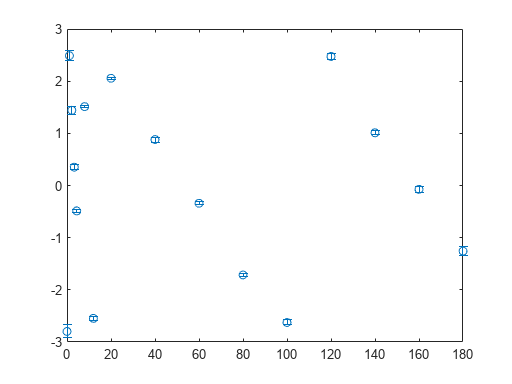

%saveas(h2,[main_dir_0,'\Period.png'])


figure
f_amp_h1=errorbar(precess_2_list',c_1,c_err_1,'o');

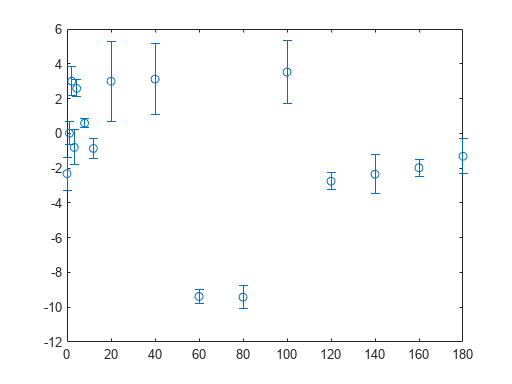

figure
f_amp_h3=errorbar(precess_2_list',c_3,c_err_5,'o');

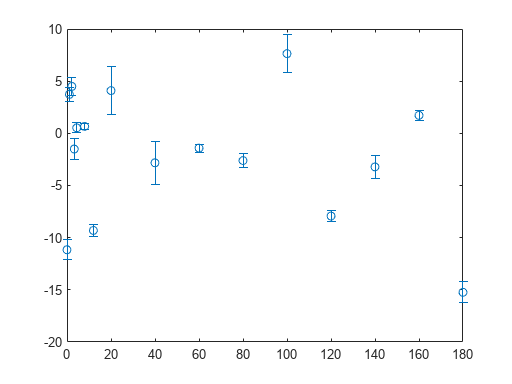

figure
f_amp_h5=errorbar(precess_2_list',c_5,c_err_5,'o');

## Plot population decay

h_p =   Figure (119) - 属性:

      Number: 119
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


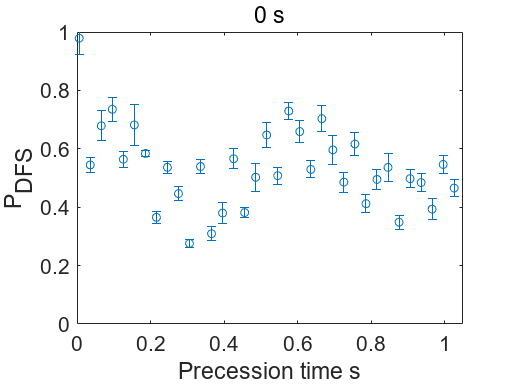

h_p =   Figure (120) - 属性:

      Number: 120
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


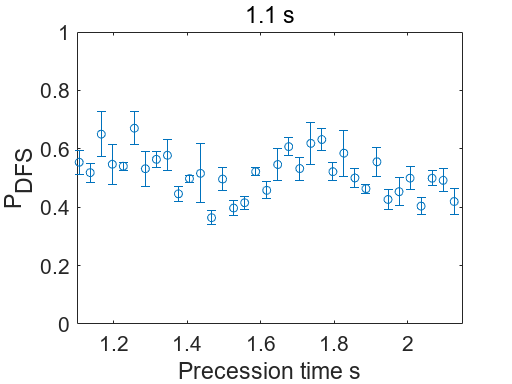

h_p =   Figure (121) - 属性:

      Number: 121
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


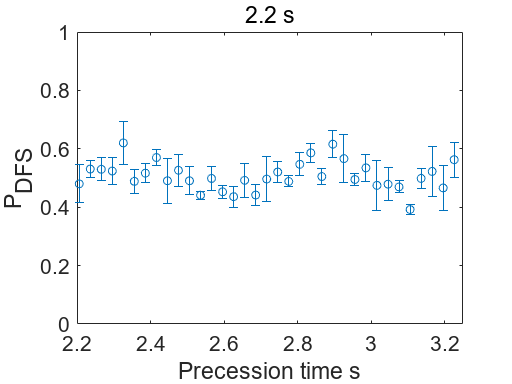

h_p =   Figure (122) - 属性:

      Number: 122
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


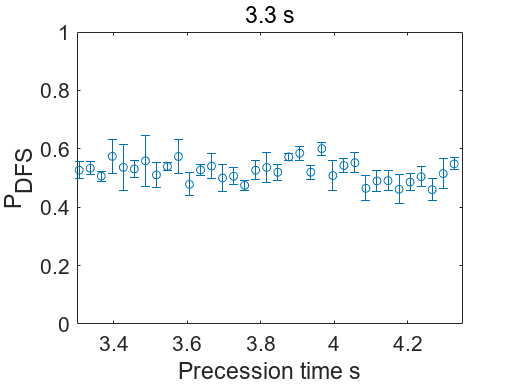

h_p =   Figure (123) - 属性:

      Number: 123
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


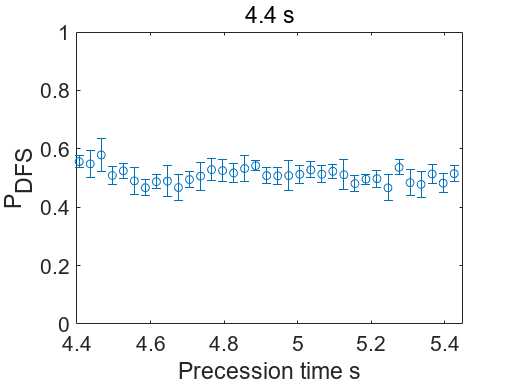

h_p =   Figure (125) - 属性:

      Number: 125
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


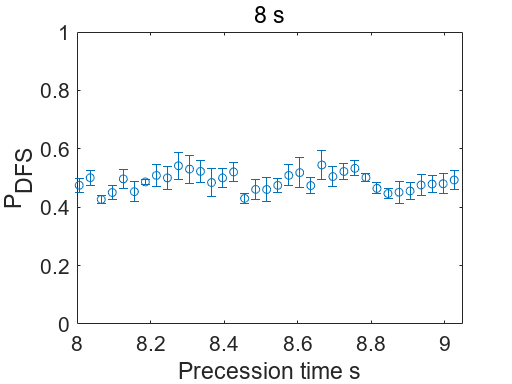

h_p =   Figure (126) - 属性:

      Number: 126
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


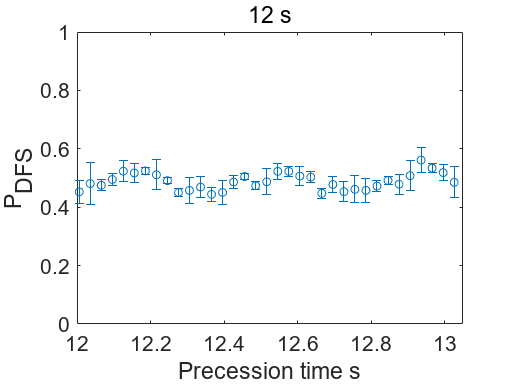

h_p =   Figure (127) - 属性:

      Number: 127
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


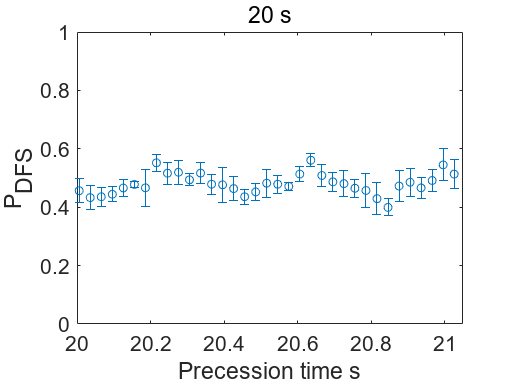

h_p =   Figure (133) - 属性:

      Number: 133
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


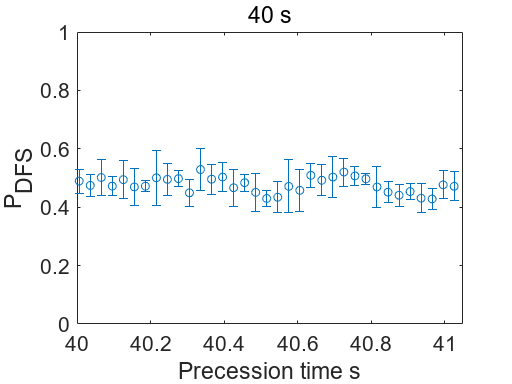

h_p =   Figure (134) - 属性:

      Number: 134
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


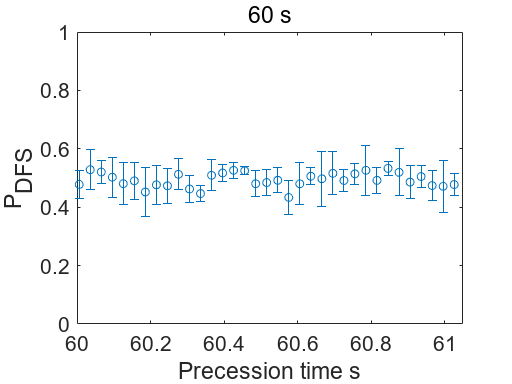

h_p =   Figure (135) - 属性:

      Number: 135
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


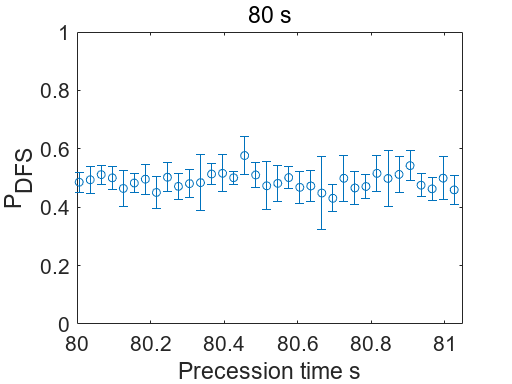

h_p =   Figure (136) - 属性:

      Number: 136
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


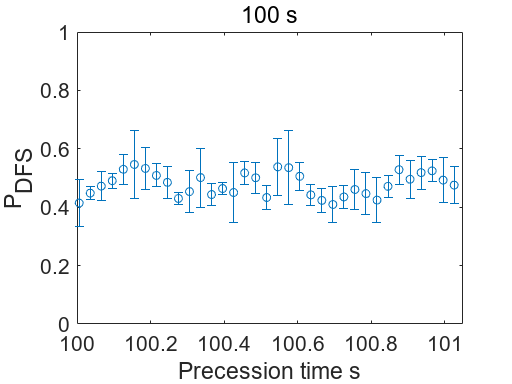

h_p =   Figure (137) - 属性:

      Number: 137
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


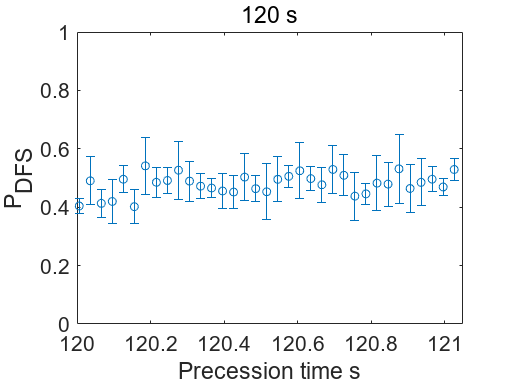

h_p =   Figure (138) - 属性:

      Number: 138
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


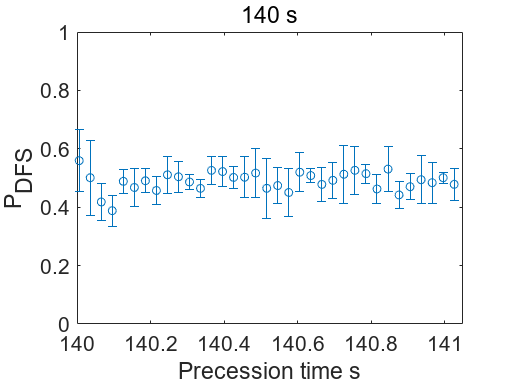

h_p =   Figure (139) - 属性:

      Number: 139
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


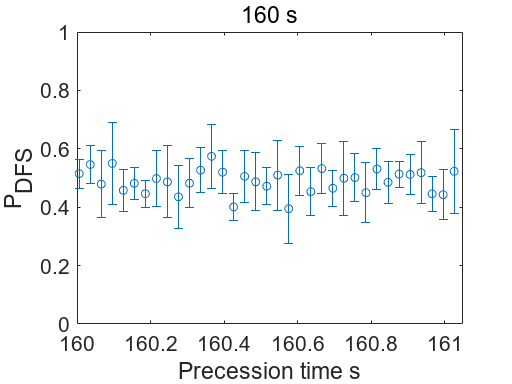

h_p =   Figure (140) - 属性:

      Number: 140
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


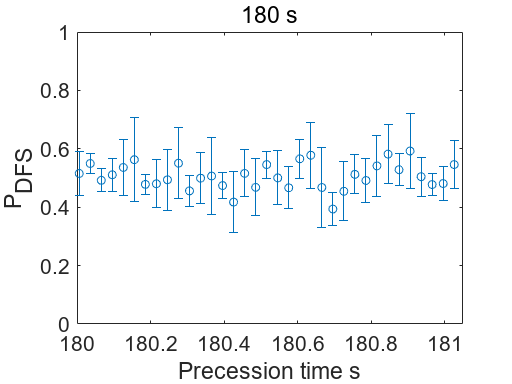

loss_factor=0.95;
for i = 1:size(mean_1,3)
    h_p=figure
    I_se=errorbar(precess_1_list+precess_2_list(i),mean_3(:,:,i)*loss_factor,std_3(:,:,i)*loss_factor,'o');
    title([num2str(precess_2_list(i)),' s']);
    ylim([0 1]);
    ylabel('P_{DFS}');
    xlabel('Precession time s');
    set(gca,'FontSize',16);
    xlim([x_lim_low+precess_2_list(i) x_lim_high+precess_2_list(i)])
    saveas(h_p,[main_dir_0,'\Figure_p_',num2str(i),'.png'])
    savefig(h_p,[main_dir_0,'\Figure_p_',num2str(i),'.fig'])
end

precess_12_list=reshape(precess_2_list+precess_1_list',[],1);
mean_3_reshape_1=reshape(mean_3,[],1);
f_pop_h_pop=errorbar(precess_12_list,reshape(mean_3,[],1),reshape(std_3,[],1),'o')

f_pop_h_pop =   ErrorBar - 属性:

             Color: [0 0.4470 0.7410]
         LineStyle: 'none'
         LineWidth: 0.5000
            Marker: 'o'
             XData: [0.0060 0.0360 0.0660 0.0960 0.1260 0.1560 0.1860 0.2160 0.2460 0.2760 0.3060 0.3360 0.3660 0.3960 0.4260 0.4560 0.4860 0.5160 0.5460 0.5760 0.6060 0.6360 0.6660 0.6960 0.7260 0.7560 0.7860 0.8160 0.8460 0.8760 0.9060 0.9360 … ]
             YData: [1.0301 0.5734 0.7145 0.7740 0.5941 0.7176 0.6148 0.3845 0.5648 0.4701 0.2903 0.5678 0.3255 0.4001 0.5956 0.4017 0.5291 0.6814 0.5347 0.7678 0.6937 0.5573 0.7403 0.6277 0.5113 0.6488 0.4338 0.5212 0.5646 0.3669 0.5238 0.5100 … ]
    XNegativeDelta: [1×0 double]
    XPositiveDelta: [1×0 double]
    YNegativeDelta: [0.0582 0.0267 0.0545 0.0435 0.0283 0.0733 0.0119 0.0228 0.0213 0.0260 0.0136 0.0264 0.0246 0.0370 0.0367 0.0176 0.0503 0.0438 0.0311 0.0300 0.0393 0.0310 0.0458 0.0519 0.

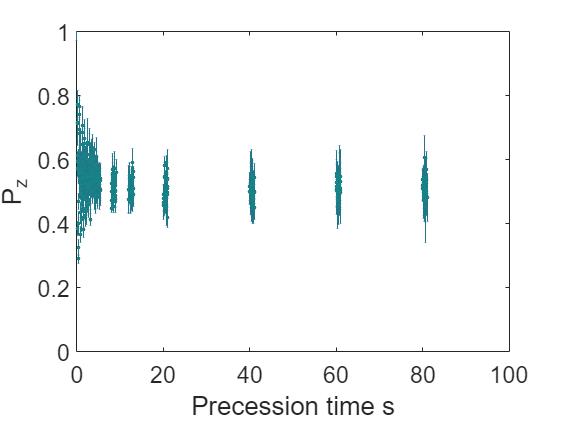


f_pop_h_pop.CapSize=1;
f_pop_h_pop.Color=colors(29,:);
f_pop_h_pop.MarkerSize=2;
f_pop_h_pop.MarkerEdgeColor=colors(28,:);
f_pop_h_pop.MarkerFaceColor=colors(25,:);

ylim([0 1]);
ylabel('P_z');
xlabel('Precession time s');
set(gca,'FontSize',16);
xlim([x_lim_low 100])


figure


f_pop_h_pop=errorbar(precess_12_list,reshape(mean_3,[],1),reshape(std_3,[],1),'o')

f_pop_h_pop =   ErrorBar - 属性:

             Color: [0 0.4470 0.7410]
         LineStyle: 'none'
         LineWidth: 0.5000
            Marker: 'o'
             XData: [0.0060 0.0360 0.0660 0.0960 0.1260 0.1560 0.1860 0.2160 0.2460 0.2760 0.3060 0.3360 0.3660 0.3960 0.4260 0.4560 0.4860 0.5160 0.5460 0.5760 0.6060 0.6360 0.6660 0.6960 0.7260 0.7560 0.7860 0.8160 0.8460 0.8760 0.9060 0.9360 … ]
             YData: [1.0301 0.5734 0.7145 0.7740 0.5941 0.7176 0.6148 0.3845 0.5648 0.4701 0.2903 0.5678 0.3255 0.4001 0.5956 0.4017 0.5291 0.6814 0.5347 0.7678 0.6937 0.5573 0.7403 0.6277 0.5113 0.6488 0.4338 0.5212 0.5646 0.3669 0.5238 0.5100 … ]
    XNegativeDelta: [1×0 double]
    XPositiveDelta: [1×0 double]
    YNegativeDelta: [0.0582 0.0267 0.0545 0.0435 0.0283 0.0733 0.0119 0.0228 0.0213 0.0260 0.0136 0.0264 0.0246 0.0370 0.0367 0.0176 0.0503 0.0438 0.0311 0.0300 0.0393 0.0310 0.0458 0.0519 0.

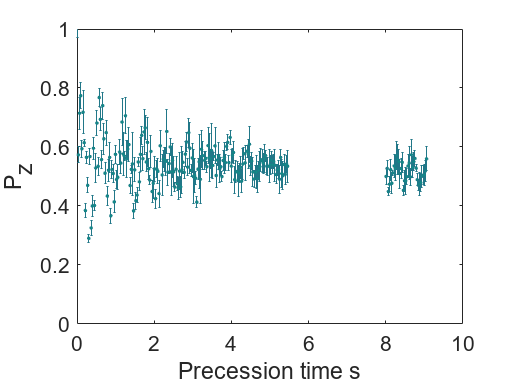


f_pop_h_pop.CapSize=1;
f_pop_h_pop.Color=colors(29,:);
f_pop_h_pop.MarkerSize=2;
f_pop_h_pop.MarkerEdgeColor=colors(28,:);
f_pop_h_pop.MarkerFaceColor=colors(25,:);

ylim([0 1]);
ylabel('P_z');
xlabel('Precession time s');
set(gca,'FontSize',16);
xlim([x_lim_low 10])

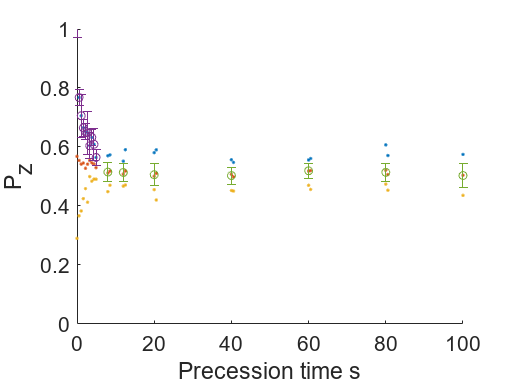





% if interrogation time  < 7s , take max values
% [0,1.1:1.1:4.4,8,12,20:20:60] data binning
% [0,1.1:1.1:4.4] % 18 points/bin 0.54 s
figure

mean_3_1=reshape(mean_3,18,1,[]);
std_3_1=reshape(std_3,18,1,[]);

[mean_3_1_max,mean_3_1_max_id]=max(mean_3_1);
mean_3_1_max_std=std_3_1(mean_3_1_max_id);
%mean_3_1_max_std=std(mean_3_1);

mean_3_max=squeeze(mean_3_1_max);
mean_3_max_std=squeeze(mean_3_1_max_std);
mean_3_max_weight=1./mean_3_max_std.^2;



precess_12_list_1=reshape(precess_2_list+[0:(18*0.03):(1.05-0.01)]',[],1);

hold on
plot(precess_12_list_1,squeeze(max(mean_3_1)),'.')
plot(precess_12_list_1,squeeze(mean(mean_3_1)),'.')
plot(precess_12_list_1,squeeze(min(mean_3_1)),'.')


% CUT OFF AT 7 SECONDS
precess_2_list_1=precess_12_list_1(precess_12_list_1<7);
mean_3_max=mean_3_max(precess_12_list_1<7);
mean_3_max_std=mean_3_max_std(precess_12_list_1<7);
mean_3_max_weight=mean_3_max_weight(precess_12_list_1<7);


errorbar(precess_2_list_1,mean_3_max,mean_3_max_std,'o')

ylim([0 1]);
ylabel('P_z');
xlabel('Precession time s');
set(gca,'FontSize',16);
xlim([x_lim_low 100])

% if interrogation time  > 7 s , take mean values

mean_3_mean=squeeze(mean(mean_3));
mean_3_mean_std=squeeze(std(mean_3));
mean_3_mean_weight=squeeze(1./mean_3_mean_std.^2);

precess_2_list_2=precess_2_list(precess_2_list>7);
mean_3_mean=mean_3_mean(precess_2_list>7);
mean_3_mean_std=mean_3_mean_std(precess_2_list>7);
mean_3_mean_weight=mean_3_mean_weight(precess_2_list>7);

errorbar(precess_2_list_2,mean_3_mean,mean_3_mean_std,'o')



precess_2_list_12=[precess_2_list_1',precess_2_list_2];
mean_3_all=[mean_3_max',mean_3_mean'];
mean_3_all_std=[mean_3_max_std',mean_3_mean_std'];
mean_3_all_weight=[mean_3_max_weight',mean_3_mean_weight'];

% population decay-fitting


loss_factor=1/1.03;
mean_3_all=mean_3_all*loss_factor;


eqn='a*exp(-x^1/b^1)+(1-a)';
startpoints=[0.5 1];
lower=[0 0 ];
upper=[1 20];

fi_pop_coherent=fit(precess_2_list_12',mean_3_all',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',mean_3_all_weight);

chi_fit=sum((((fi_pop_coherent(precess_2_list_12))'-mean_3_all)./mean_3_all_std).^2)

chi_fit = 25.8438


chi_fit_reduced=chi_fit/(length(precess_2_list_12)-2)

chi_fit_reduced = 1.3602



fi_pop_coherent

fi_pop_coherent =      常规模型:
     fi_pop_coherent(x) = a*exp(-x^1/b^1)+(1-a)
     系数(置信边界为 95%):
       a =      0.4863  (0.4633, 0.5093)
       b =       1.285  (0.9505, 1.62)

f_pop_decay=figure

f_pop_decay =   Figure (143) - 属性:

      Number: 143
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


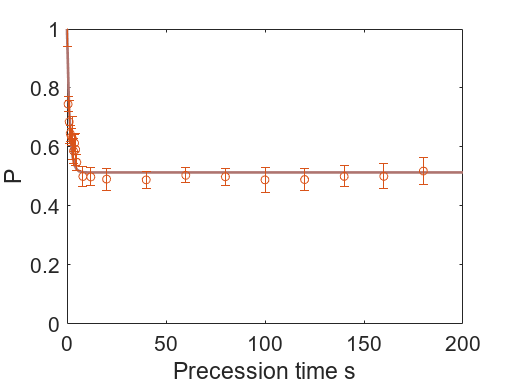

plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',2,'Color',colors(5,:));

hold on

errorbar(precess_2_list_12,mean_3_all,mean_3_all_std,'o')
ylim([0 1]);
ylabel('P');
xlabel('Precession time s');
set(gca,'FontSize',16);
xlim([x_lim_low 200])


%savefig(f_pop_decay,[main_dir_0,'\PopulationDecay.fig'])
%saveas(f_pop_decay,[main_dir_0,'\Population decay.png'])



## Plot differential

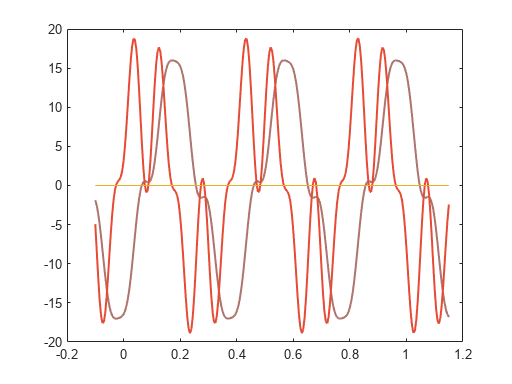

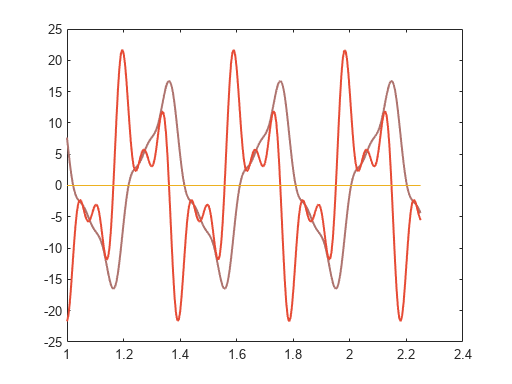

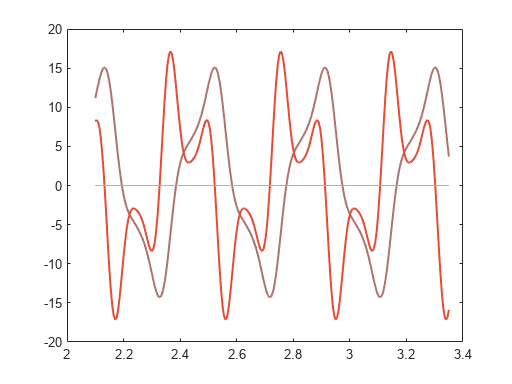

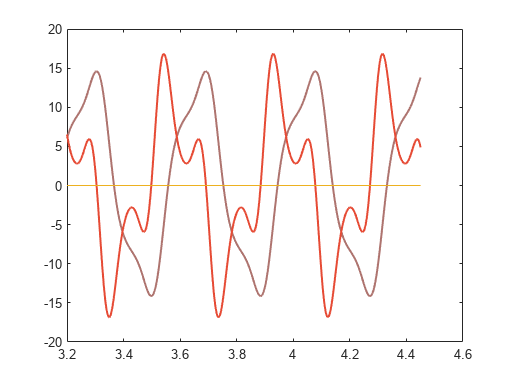

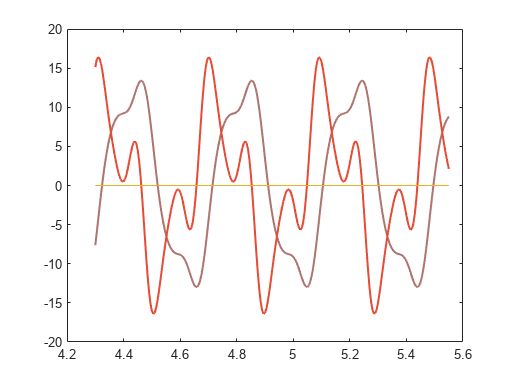

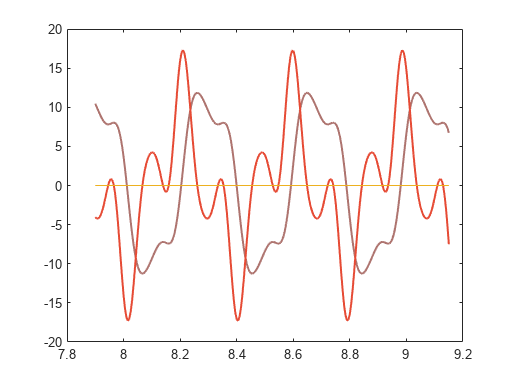

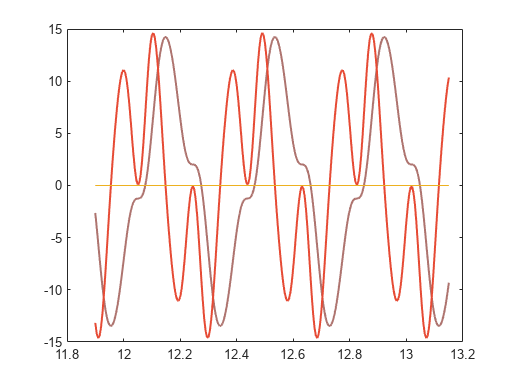

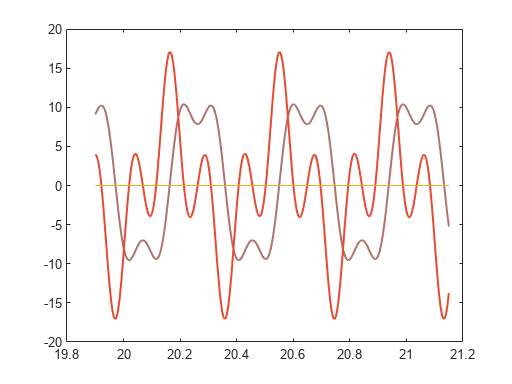

slope_max=zeros(1,size(mean_1,3));
slope_min=zeros(1,size(mean_1,3));

for i = 1:size(mean_1,3)
    [d1,d2] = differentiate(fi_result{i},precess_1_list_plot);
    slope_max(i)=max(d1);
    slope_min(i)=-min(d1);
    fi=fi_result{i};
    fi_parameter_bound=confint(fi);
    figure
    plot(precess_1_list_plot+precess_2_list(i),fi(precess_1_list_plot)*20,'LineWidth',1.5,'Color',colors(5,:));
    hold on
    plot(precess_1_list_plot+precess_2_list(i),d1,'LineWidth',1.5,'Color',colors(1,:));

%     fittype_slope = fittype('-a1*2*pi*b1*sin(2*pi*b1*x+c1)-a3*2*pi*b1*3*sin(2*pi*b1*3*x+c3)-a5*2*pi*b1*5*sin(2*pi*b1*5*x+c5)');
%     param_mean = {fi.a1,fi.a3,fi.a5,fi.b1,fi.c1,fi.c3,fi.c5};
%     param_up ={fi_parameter_bound(2),fi_parameter_bound(4),fi_parameter_bound(6),fi_parameter_bound(8),fi_parameter_bound(10),fi_parameter_bound(12),fi_parameter_bound(14)};
%     param_low={fi_parameter_bound(1),fi_parameter_bound(3),fi_parameter_bound(5),fi_parameter_bound(7),fi_parameter_bound(9),fi_parameter_bound(11),fi_parameter_bound(13)};
% 
%     fit_slope=cfit(fittype_slope,param_mean{:});
%     fit_slope_up=cfit(fittype_slope,param_up{:});
%     fit_slope_low=cfit(fittype_slope,param_low{:});
% 
%     slope_mean=plot(precess_1_list_plot+precess_2_list(i),fit_slope(precess_1_list_plot),'Linewidth',1)
% 
%     slope_up=plot(precess_1_list_plot+precess_2_list(i),fit_slope_up(precess_1_list_plot),'Linewidth',1)
% 
%     slope_low=plot(precess_1_list_plot+precess_2_list(i),fit_slope_low(precess_1_list_plot),'Linewidth',1)
%     legend([slope_low,slope_mean,slope_up],{'low','mean','up'})
%     %plot(precess_1_list_plot+precess_2_list(i),d2/50,'LineWidth',1.5,'Color',colors(27,:));
%     hold on
    plot(precess_1_list_plot+precess_2_list(i),zeros(1,length(precess_1_list_plot+precess_2_list(i))))
    
end


precess_2_list_sensitivity=precess_2_list+mean(precess_1_list);

amp_all=amp_1+3*amp_3+5*amp_5;
amp_all_err=amp_err_1+3*amp_err_3+5*amp_err_5;

%amp_all_err(isnan(amp_all_err))=sqrt(1/10)*amp_all(isnan(amp_all_err));


sensitivity=1./precess_2_list_sensitivity./slope_max*1.2424e+03./((fi_pop_coherent(precess_2_list_sensitivity)).^0.5)';
sensitivity_error=(amp_all_err./amp_all).*sensitivity;
sensitivity_decay=figure;
%scatter(precess_2_list_sensitivity,sensitivity)
hold on
errorbar(precess_2_list_sensitivity(3:end),sensitivity(3:end),sensitivity_error(3:end),'o')
set(gca,'XScale','log')
set(gca,'YScale','log')
xlim([0.1 200])
ylim([1e-2 100])
hold on

savefig(sensitivity_decay,[main_dir_0,'\SensitivityDecay.fig'])

hold on

g_I=0.27102;
nuclear_magneton=2*pi*7.6225932291*10^6;%Hz/T
gyro_factor=g_I*nuclear_magneton;

HL=plot(0.001:0.1:500,1./(0.001:0.1:500)/(5)/(gyro_factor/10^9))

HL =   Line - 属性:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1.0000e-03 0.1010 0.2010 0.3010 0.4010 0.5010 0.6010 0.7010 0.8010 0.9010 1.0010 1.1010 1.2010 1.3010 1.4010 1.5010 1.6010 1.7010 1.8010 1.9010 2.0010 2.1010 2.2010 2.3010 2.4010 2.5010 2.6010 2.7010 2.8010 2.9010 3.0010 3.1010 … ]
              YData: [1.5408e+04 152.5544 76.6567 51.1893 38.4239 30.7545 25.6373 21.9800 19.2359 17.1010 15.3926 13.9945 12.8293 11.8432 10.9979 10.2652 9.6240 9.0582 8.5552 8.1052 7.7001 7.3336 7.0005 6.6962 6.4173 6.1607 5.9239 5.7046 5.5009 … ]

  显示 所有属性


SQL=plot(0.001:0.1:500,1./(0.001:0.1:500)/(sqrt(5))/(gyro_factor/10^9))

SQL =   Line - 属性:

              Color: [0.9290 0.6940 0.1250]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1.0000e-03 0.1010 0.2010 0.3010 0.4010 0.5010 0.6010 0.7010 0.8010 0.9010 1.0010 1.1010 1.2010 1.3010 1.4010 1.5010 1.6010 1.7010 1.8010 1.9010 2.0010 2.1010 2.2010 2.3010 2.4010 2.5010 2.6010 2.7010 2.8010 2.9010 3.0010 3.1010 … ]
              YData: [3.4453e+04 341.1220 171.4095 114.4628 85.9185 68.7691 57.3267 49.1488 43.0129 38.2390 34.4189 31.2927 28.6872 26.4822 24.5919 22.9536 21.5199 20.2547 19.1301 18.1238 17.2180 16.3985 15.6535 14.9732 14.3496 13.7758 13.2462 … ]

  显示 所有属性


mixed=plot(0.001:0.1:500,1./(0.001:0.1:500)/(5/sqrt(16))/(gyro_factor/10^9))

mixed =   Line - 属性:

              Color: [0.4940 0.1840 0.5560]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1.0000e-03 0.1010 0.2010 0.3010 0.4010 0.5010 0.6010 0.7010 0.8010 0.9010 1.0010 1.1010 1.2010 1.3010 1.4010 1.5010 1.6010 1.7010 1.8010 1.9010 2.0010 2.1010 2.2010 2.3010 2.4010 2.5010 2.6010 2.7010 2.8010 2.9010 3.0010 3.1010 … ]
              YData: [6.1632e+04 610.2175 306.6267 204.7574 153.6957 123.0179 102.5490 87.9201 76.9438 68.4040 61.5704 55.9782 51.3172 47.3728 43.9914 41.0606 38.4959 36.2328 34.2210 32.4208 30.8006 29.3346 28.0018 26.7849 25.6693 24.6429 23.6955 … ]

  显示 


eqn='a/x';
startpoints=[100];
lower=[1 ];
upper=[1000];

fi=fit(precess_2_list_sensitivity',sensitivity',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./sensitivity_error.^2,'Exclude',precess_2_list<2);
fi

fi =      常规模型:
     fi(x) = a/x
     系数(置信边界为 95%):
       a =       107.5  (101, 114)

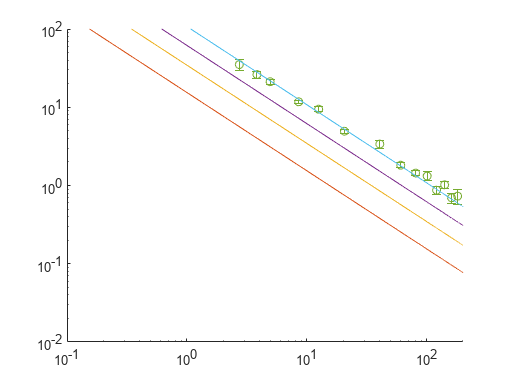

errorbar(precess_2_list_sensitivity(3:end),sensitivity(3:end),sensitivity_error(3:end),'o')
hold on
plot(0.01:0.1:300,fi(0.01:0.1:300))
set(gca,'XScale','log')
set(gca,'YScale','log')
xlim([0.1 200])
ylim([1e-2 100])

## Sensitivity when phase matched

% for i = 1:size(mean_1,3)
%     fi=fi_result{i};
%     a1=fi.a1;
%     a3=fi.a3;
%     a5=fi.a5;
%     b1=fi.b1;
%     d=fi.d;
% 
%     f = fittype('a1*cos(2*pi*b1*x)+a3*cos(2*pi*b1*3*x+pi)+a5*cos(2*pi*b1*5*x)+d');
%     fi_pm = cfit(f,a1,a3,a5,b1,d);
% 
%     [d1,d2] = differentiate(fi_pm,precess_1_list_plot);
%     slope_max(i)=max(d1);
%     slope_min(i)=-min(d1);
%     fi=fi_result{i};
%     fi_parameter_bound=confint(fi);
%     figure
%     plot(precess_1_list_plot+precess_2_list(i),fi_pm(precess_1_list_plot)*20,'LineWidth',1.5,'Color',colors(5,:));
%     hold on
%     plot(precess_1_list_plot+precess_2_list(i),d1,'LineWidth',1.5,'Color',colors(1,:));
% end
% 
% precess_2_list_sensitivity=precess_2_list+mean(precess_1_list);
% 
% amp_all=amp_1+3*amp_3+5*amp_5;
% amp_all_err=sqrt(amp_err_1.^2+9*amp_err_3.^2+25*amp_err_5.^2);
% 
% amp_all_err(isnan(amp_all_err))=sqrt(1/10)*amp_all(isnan(amp_all_err));
% 
% 
% sensitivity=1./precess_2_list_sensitivity./slope_max*12.5*100./(fi_pop_coherent(precess_2_list_sensitivity))';
% sensitivity_error=amp_all_err./amp_all.*sensitivity./(fi_pop_coherent(precess_2_list_sensitivity))';
% sensitivity_decay=figure;
% %scatter(precess_2_list_sensitivity,sensitivity)
% hold on
% errorbar(precess_2_list_sensitivity,sensitivity,sensitivity_error,'o')
% set(gca,'XScale','log')
% set(gca,'YScale','log')
% xlim([0.1 200])
% ylim([1e-2 100])
% hold on
% 
% HL=plot(0.001:0.1:500,1./(0.001:0.1:500)/(5)/(1.298e-2))
% SQL=plot(0.001:0.1:500,1./(0.001:0.1:500)/(sqrt(5))/(1.298e-2))
% mixed=plot(0.001:0.1:500,1./(0.001:0.1:500)/(5/sqrt(16))/(1.298e-2))

## Vacuum decay

% number decay
figure;
n_list=squeeze(mean_2(:,:,:));
n_std=squeeze(std_2(:,:,:));
[n_max,n_max_index]=max(n_list);
n_fit_weight=1./n_std.^2;

n_norm=n_list./n_max;
n_std_norm=n_std./n_max;

eqn='exp(-x/a)*b';
startpoints=[50 1];
lower=[20 0];
upper=[100 1];

fi=fit(precess_2_list(1:end)',n_norm(1:end),eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',n_fit_weight(1:end));
h=figure;
plot((0:1:200),fi(0:1:200),'LineWidth',1.5,'Color',colors(5,:));
hold on

fi.a

ans = 76.0326

temp = confint(fi);
(temp(2,:)-temp(1,:))/4

ans =     5.9397    0.0500


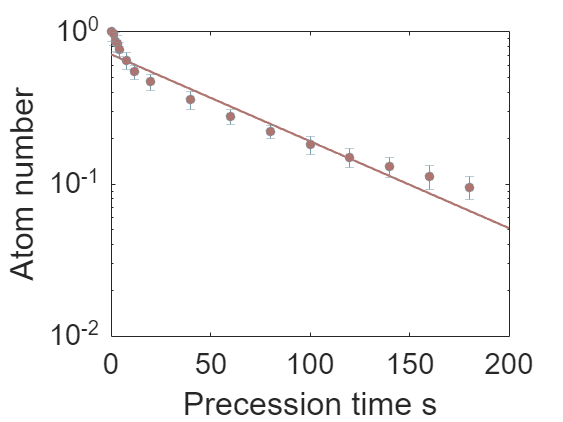


h3=errorbar(precess_2_list',n_norm,n_std_norm,'o');


ylabel('Atom number');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
h3.Color=colors(9,:);
h4.MarkerSize=6;
h3.MarkerEdgeColor=colors(8,:);
h3.MarkerFaceColor=colors(5,:);
set(gca,'YScale','log')
ylim([0.01 1])

## Fitting Amp Decay

amp_all=amp_1+amp_3+amp_5;
amp_all_err=amp_err_1+amp_err_3+amp_err_5;
amp_list=amp_all;
amp_error=amp_all_err;

amp_error(isnan(amp_error))=max(amp_error);

chilist_reduced(chilist_reduced<1)=1;
%amp_error=amp_error.*sqrt(chilist_reduced)

amp_weight=1./amp_error.^2;

eqn='exp(-x/b)*(c*exp(-x/d)+1-c)';
startpoints=[500 0.2 1];
lower=[100 0 0.1];
upper=[2000 1 10];

fi=fit(precess_2_list',amp_list',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',amp_weight,'Exclude',precess_2_list<2);
fi

fi =      常规模型:
     fi(x) = exp(-x/b)*(c*exp(-x/d)+1-c)
     系数(置信边界为 95%):
       b =       747.6  (540.2, 955.1)
       c =      0.2697  (0.2496, 0.2898)
       d =       2.459  (1.578, 3.339)

fi.b

ans = 747.6441


fi_coef=confint(fi);
(fi_coef(2,:)-fi_coef(1,:))/4

ans =   103.7086    0.0100    0.4403


f_amp_decay=figure;

plot((0:0.1:200),fi(0:0.1:200),'LineWidth',1.5,'Color',colors(5,:));
hold on

chi_fit=sum((((fi(precess_2_list(3:end)))'-amp_list(3:end))./amp_error(3:end)).^2)

chi_fit = 3.9565


chi_fit_reduced=chi_fit/(length(precess_2_list)-2-2)

chi_fit_reduced = 0.3297


hold on


temp = confint(fi);
(temp(2,:)-temp(1,:))/4

ans =   103.7086    0.0100    0.4403


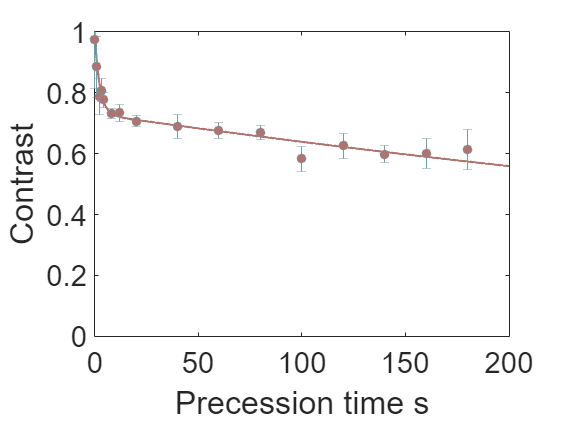


h3=errorbar(precess_2_list(1:end)',amp_list(1:end),amp_error(1:end),'o');


ylabel('Contrast');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
h3.Color=colors(9,:);
h4.MarkerSize=6;
h3.MarkerEdgeColor=colors(8,:);
h3.MarkerFaceColor=colors(5,:);
set(gca,'YScale','linear')
ylim([0 1])

% savefig(f_amp_decay,[main_dir_0,'\AmpDecay.fig'])
% saveas(f_amp_decay,[main_dir_0,'\Contrast decay.png'])

## Save result

save([main_dir_0,'\average.mat'])